On souhaite trouver la solution de l'équation $u_{xx}-(x^6+3x^2)u = 0.$

Avec conditions initiales $u(-1) = u(1)  =1$.

On suppose une solution de la forme: $u_2(x) = 1 + (1-x^2)(a_0+a_1x+a_2x^2)$

syms x a0 a1 a2

u = 1 + (1-x^2)*(a0+a1*x+a2*x^2);
uxx = diff(u,x,2);
V = (x^6+3*x^2);

On parvient à l'équation résiduelle:

R = uxx-u*V;
%L'equation residuelle
R = collect(R,x)

$$R = a_{2}\,x^{10}+a_{1}\,x^{9}+\left(a_{0}-a_{2}\right)\,x^{8}+\left(-a_{1}\right)\,x^{7}+\left(3\,a_{2}-a_{0}-1\right)\,x^{6}+\left(3\,a_{1}\right)\,x^{5}+\left(3\,a_{0}-3\,a_{2}\right)\,x^{4}+\left(-3\,a_{1}\right)\,x^{3}+\left(-3\,a_{0}-12\,a_{2}-3\right)\,x^{2}+\left(-6\,a_{1}\right)\,x+2\,a_{2}-2\,a_{0}$$

On choici 3 points de collocations $\{-0.5,0,0.5\}$ où l'on remplace x en assumant qu'il s'agit d'une solution exacte.

Ainsi on parvient à 3 équations du type $R(x_i;a_0,a_1,a_2) =0$ qui engendre un système d'équation pour les coefficients.

xi = [-0.5,0,0.5];

R1 = subs(R,x,xi(1))

$$R1 = \frac{1683\,a_{1}}{512}-\frac{659\,a_{0}}{256}-\frac{1171\,a_{2}}{1024}-\frac{49}{64}$$

R2 = subs(R,x,xi(2))

$$R2 = 2\,a_{2}-2\,a_{0}$$

R3 = subs(R,x,xi(3))

$$R3 = -\frac{659\,a_{0}}{256}-\frac{1683\,a_{1}}{512}-\frac{1171\,a_{2}}{1024}-\frac{49}{64}$$


solve([R1,R2,R3],[a0,a1,a2])

ans = struct with fields:
    a0: -784/3807
    a1: 0
    a2: -784/3807


En sachant que la vraie solution est $u(x) = e^{\frac{x^4-1}{4}$. On peut calculer l'erreur:

xx = linspace(-1,1);

uexact = exp(0.25*(x^4-1));
uexact = matlabFunction(uexact);
u2 = subs(u,[a0,a1,a2],[-784/3807,0,-784/3807])

$$u2 = \left(x^{2}-1\right)\,\left(\frac{784\,x^{2}}{3807}+\frac{784}{3807}\right)+1$$

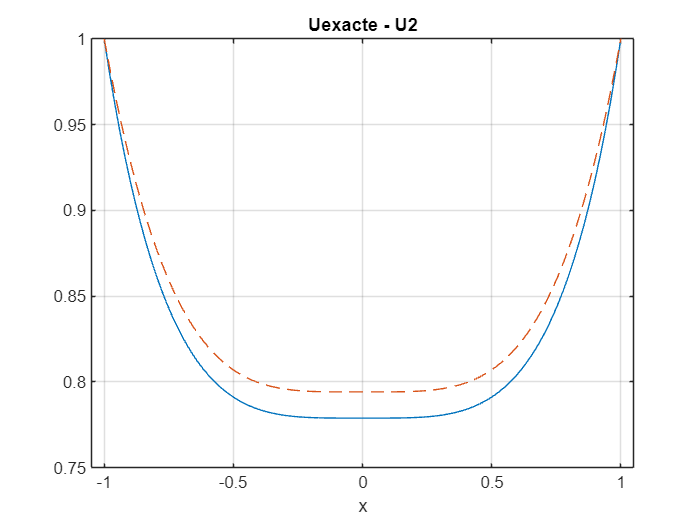

u2 = matlabFunction(u2);

plot(xx,uexact(xx))
hold on
plot(xx,u2(xx),'--')
hold off
title('Uexacte - U2')
xlabel('x')
xlim([-1.05,1.05])
grid on
saveas(gcf, 'uexact_vs_u2.png')

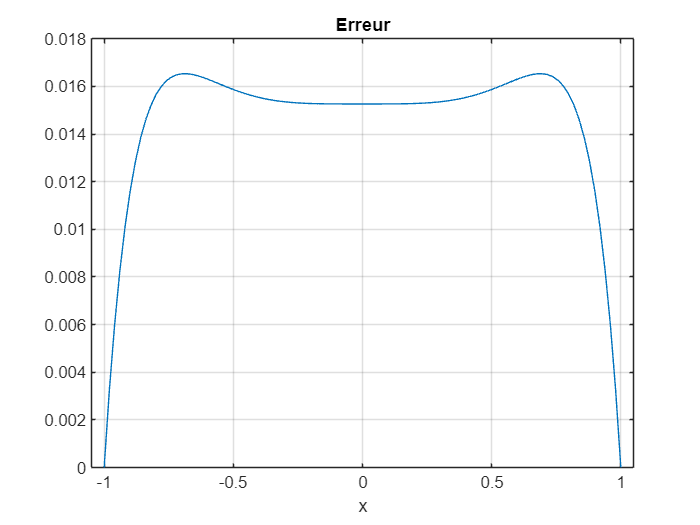



plot(xx, abs(u2(xx)-uexact(xx)))
title('Erreur')
xlabel('x')
xlim([-1.05,1.05])
grid on
saveas(gcf, 'erreur1.png')